mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
u = mMoon/(mEarth + mMoon)

u = 0.0122

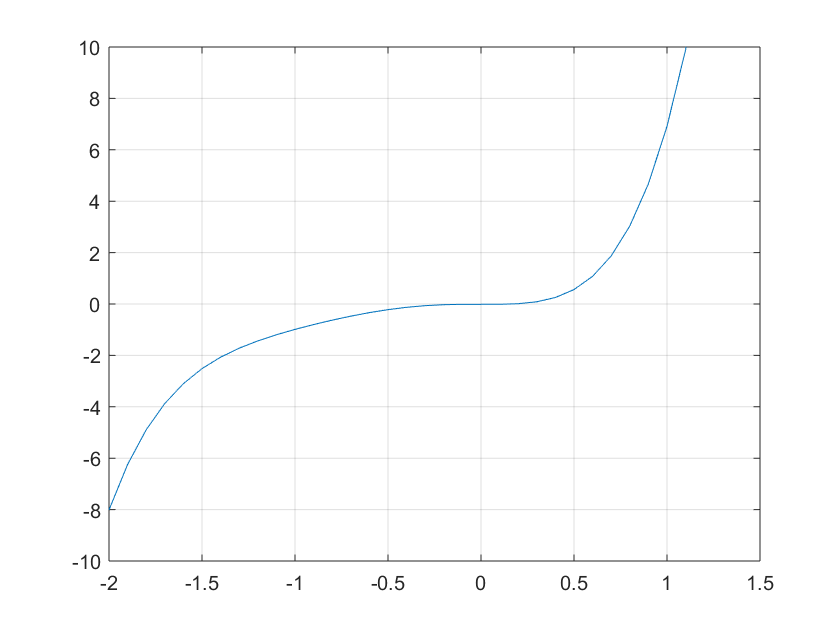

quintic = @(x) x.^5 + (3-u)*x.^4 + (3-2*u)*x.^3 -u*x.^2 -2*u*x -u;
Dx_quintic = @(x) 5*x.^4 + 4*(3-u)*x.^3 + 3*(3-2*u)*x.^2 -2*u*x -2*u;

x = -2:0.1:2;
plot(x,quintic(x))
ylim([-10 10])
grid on
hold on

x0 = (u/3)^(1/3)

x0 = 0.1594

x1 = newtonMethod(quintic,Dx_quintic,x0,2000,1e-15);
L2 = vpa(u)-1 - vpa(x1)

$$L2 = -1.156234303$$



quintic2 = @(x) x.^5 - (3-u)*x.^4 + (3-2*u)*x.^3 -u*x.^2 +2*u*x -u;
Dx_quintic2 = @(x) 5*x.^4 - 4*(3-u)*x.^3 + 3*(3-2*u)*x.^2 -2*u*x +2*u;
x2 = newtonMethod(quintic2,Dx_quintic2,x0,3000,1e-15)

x2 = 0.1509

L1 = vpa(u)-1 + vpa(x2)

$$L1 = -0.8369174475$$


quintic3 = @(x) x^5 + (2+u)*x^4 + (1+2*u)*x^3 - (1-u)*x^2 - 2*(1-u)*x - (1-u);
Dx_quintic3 = @(x) 5*x^4 + 4*(2+u)*x^3 + 3*(1+2*u)*x^2 - 2*(1-u) - 2*(1-u);
x0 = 1 - (7/12)*u;
x3 = newtonMethod(quintic3,Dx_quintic3,x0,3000,1e-15);
L3 = vpa(u) + vpa(x3)

$$L3 = 1.005062449$$


%cal L4
L4x = 1/2 - u 

L4x = 0.4878

vpa(L4x)

$$ans = 0.4878498862$$

L4y = 3^(1/2)/2

L4y = 0.8660

vpa(L4y)

$$ans = 0.8660254038$$

%cal L5
L5x = L4x

L5x = 0.4878

L5y = -3^(1/2)/2

L5y = -0.8660

vpa(L5y)

$$ans = -0.8660254038$$